clear;
close all;
clc;
opts = bodeoptions('cstprefs');
opts.FreqUnits = 'Hz';

s = tf('s');


### 690V scenario trafo

Pnom = 1600e3; % potenza nominale apparente trafo di media: 35kV/690V 1600kVA
Unom = 690;
fnom = 50; 
Inom = Pnom/sqrt(3)/Unom;
Ucc = 0.06; % tensione di corto circuito, dato di targa
L2 = Ucc * Unom/sqrt(3)/Inom/(2*pi*fnom) % calcolo della induttanza dispersa trafo

L2 = 5.6830e-05

RL2 = 0.02 * Pnom/3/Inom^2

RL2 = 0.0060

### dato filtro attuale 690V

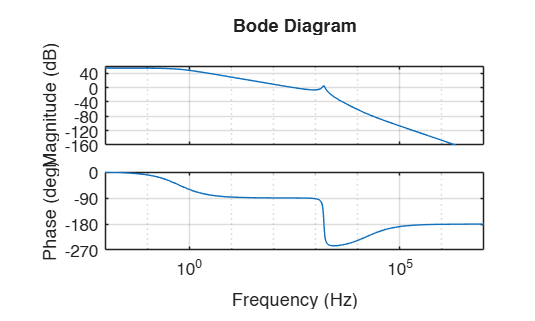

L1 = 500e-6;
RL1 = 2e-3;
RC = 50e-3;
C = 200e-6;
% L2 = 65e-6; % leakage transformer e.g. 5% di 1600 kVA 690V
% RL2 = 2e-3; % in generale per il trafo è 1-2% della potenza apparente nominale e.g. RL2 = 0.02*1.6e6/3/Inom^2

ZL1 = s*L1 + RL1;
ZRC = RC + 1/s/C;
ZL2 = s*L2;

% funzione di trasferimento tra Us (uscita inverter) e ig (corrente sul
% trafo)

Zp2 = minreal(ZL2 * ZRC / (ZL2 + ZRC));

% is = us/(Zp2 + ZL1); 
% ug = is * Zp2;
% ig = ug / ZL2;

H_ig_us = minreal(Zp2/((Zp2 + ZL1) * ZL2));
figure; bode(H_ig_us, opts); grid on


fres = 1/(2*pi*sqrt(C*L2)) % questa risonanza crea problemi sui vincoli delle interarmoniche

fres = 1.4928e+03

### dato filtro 690V scenario 1

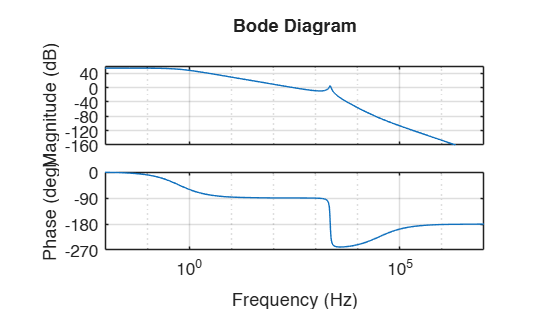

L1 = 500e-6;
RL1 = 2e-3;
RC = 50e-3;
C = 120e-6;

ZL1 = s*L1 + RL1;
ZRC = RC + 1/s/C;
ZL2 = s*L2;

Zp2 = minreal(ZL2 * ZRC / (ZL2 + ZRC));

H_ig_us = minreal(Zp2/((Zp2 + ZL1) * ZL2));
figure; bode(H_ig_us, opts); grid on


fres = 1/(2*pi*sqrt(C*L2)) % questa risonanza crea problemi sui vincoli delle interarmoniche

fres = 2.1112e+03